# **Tutorial 2: Vectors, Matrices and Operations**

### Section 1: Vectors

**Defining / initializing vectors:**

fprintf('creating v:')

creating v:


v = [1 2 3 4]  %1x4 vector (row vector)

v =      1     2     3     4



fprintf('creating w:')

creating w:


w = transpose([3,4,5,6])  %4x1 vector (column vector)

w =      3
     4
     5
     6




%Or we could do:
w = [3;4;5;6] %this creates a column vector

w =      3
     4
     5
     6



fprintf('creating y:')

creating y:


y = 1:4 % 1x4 vector

y =      1     2     3     4



fprintf('creating z:')

creating z:


z = 1:3:10 %1x4 vector : 1, 4, 7, 10 (first, step, last)

z =      1     4     7    10



fprintf('Let us go beyond range:')

Let us go beyond range:

z = 1:6:5

z = 1


z= 1:2:6 

z =      1     3     5



%Question - how can you generate 9, 7, 5, 3, 1?


**Initializing using linspace (similar to Python):**


%help linspace
x= linspace(1,100)%default is N = 100

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x = linspace(1,100,50)

x =     1.0000    3.0204    5.0408    7.0612    9.0816   11.1020   13.1224   15.1429   17.1633   19.1837   21.2041   23.2245   25.2449   27.2653   29.2857   31.3061   33.3265   35.3469   37.3673   39.3878   41.4082   43.4286   45.4490   47.4694   49.4898   51.5102   53.5306   55.5510   57.5714   59.5918   61.6122   63.6327   65.6531   67.6735   69.6939   71.7143   73.7347   75.7551   77.7755   79.7959   81.8163   83.8367   85.8571   87.8776   89.8980   91.9184   93.9388   95.9592   97.9796  100.0000


x(end)

ans = 100

max(x)

ans = 100

x = linspace(1,99,50) 

x =      1     3     5     7     9    11    13    15    17    19    21    23    25    27    29    31    33    35    37    39    41    43    45    47    49    51    53    55    57    59    61    63    65    67    69    71    73    75    77    79    81    83    85    87    89    91    93    95    97    99



%help logspace

a = logspace(1,5, 5)

a =           10         100        1000       10000      100000


b = logspace(10,2) %default is 50

b = 1.0e+10 *

    1.0000    0.6866    0.4715    0.3237    0.2223    0.1526    0.1048    0.0720    0.0494    0.0339    0.0233    0.0160    0.0110    0.0075    0.0052    0.0036    0.0024    0.0017    0.0012    0.0008    0.0005    0.0004    0.0003    0.0002    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


b(50)

ans = 100

%Initializing using blocks
v

v =      1     2     3     4


w

w =      3
     4
     5
     6



newvec = [v, transpose(w)] %remember blocks?

newvec =      1     2     3     4     3     4     5     6



newvec(4)

ans = 4


newvec(4:6)

ans =      4     3     4



newvec([1,3, 5])

ans =      1     3     3



newvec(6)= 50

newvec =      1     2     3     4     3    50     5     6



newvec([9,10]) = [0, 500]

newvec =      1     2     3     4     3    50     5     6     0   500


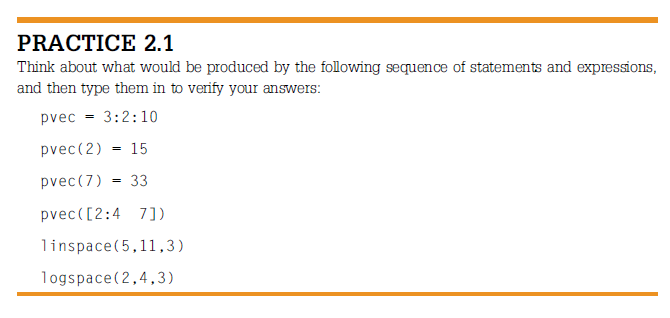

%Answer here:
logspace(2,4,3)

ans =          100        1000       10000


vec = [10^2 10^3 10^4]

vec =          100        1000       10000


log10(vec)

ans =      2     3     4


**Operations on vectors:**


v

v =      1     2     3     4


w

w =      3
     4
     5
     6


z

z =      1     3     5



fprintf('Addition:')

Addition:

v+w

ans =      4     5     6     7
     5     6     7     8
     6     7     8     9
     7     8     9    10


v+transpose(w)

ans =      4     6     8    10



fprintf('Subtraction:')

Subtraction:

%w-transpose(z) %- error
w - transpose(v)

ans =      2
     2
     2
     2





fprintf('Multiplication by scalar:')

Multiplication by scalar:


c = 5

c = 5

c*v

ans =      5    10    15    20


v*c

ans =      5    10    15    20


v

v =      1     2     3     4


w

w =      3
     4
     5
     6


z

z =      1     3     5


fprintf("Multiplication of vectors:")

Multiplication of vectors:

v*w

ans = 50


w*v

ans =      3     6     9    12
     4     8    12    16
     5    10    15    20
     6    12    18    24


%v*transpose(w)

%v*z
%z*v
%z*transpose(v) %- error
% v*transpose(z) - error

%referring to an entry:
v(3)

ans = 3

### Section 2: Matrices

**Defining / initializing matrices:**

v = 1:3

v =      1     2     3


w = 4:6

w =      4     5     6


mat= [v;w]

mat =      1     2     3
     4     5     6


mat = [1, 2, 3; 4, 5, 6]

mat =      1     2     3
     4     5     6


size(mat)

ans =      2     3



%mat = [1, 2, 3; 4, 5] %- error
%Referring to elements:
mat(2,3) %Ans: 6

ans = 6

mat(1,:) %return the first row of the matrix

ans =      1     2     3


mat(:,1) %return the first column of the matrix

ans =      1
     4



zeros(5)

ans =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


zeros(2,3)

ans =      0     0     0
     0     0     0


zeros(size(mat))

ans =      0     0     0
     0     0     0


ones(5)

ans =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


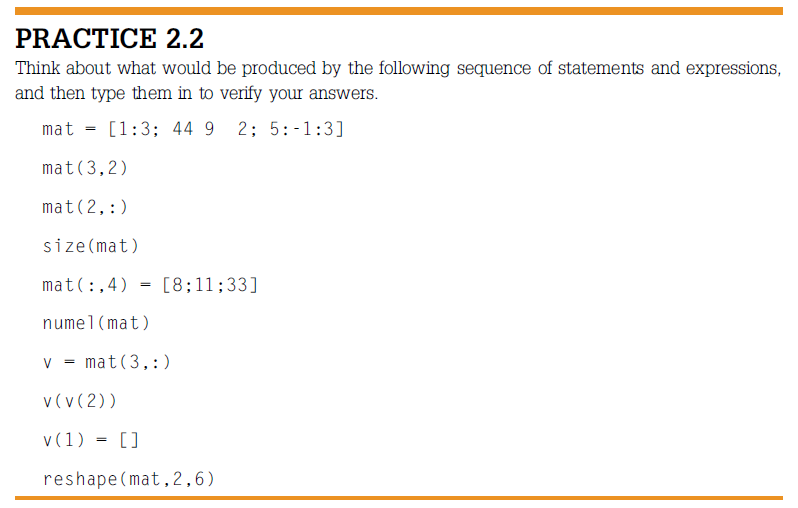

%Answer here:
mat = [1:3; 44 9 2; 5:-1:3]

mat =      1     2     3
    44     9     2
     5     4     3


mat(3,2)

ans = 4

mat(2,:)

ans =     44     9     2


size(mat)

ans =      3     3


mat(:, 4) = [8;11;33]

mat =      1     2     3     8
    44     9     2    11
     5     4     3    33


numel(mat)

ans = 12

v = mat(3, :)

v =      5     4     3    33


v(1) = []

v =      4     3    33


mat

mat = 3×4
     1     2     3     8
    44     9     2    11
     5     4     3    33


reshape(mat, 1, 12)

ans = 1×12
     1    44     5     2     9     4     3     2     3     8    11    33


reshape(mat, 6, 2)

ans = 6×2
     1     3
    44     2
     5     3
     2     8
     9    11
     4    33


**Matrix operations and functions:**

mat

mat = 3×4
     1     2     3     8
    44     9     2    11
     5     4     3    33


%mat*2

%mat+mat %equivalent to 2*mat

%mat-2*mat %equivalent to mat*(-1)

transpose(mat)

ans = 4×3
     1    44     5
     2     9     4
     3     2     3
     8    11    33


mat_2 = [4, 3; 1, 1; 5, 5]

mat_2 = 3×2
     4     3
     1     1
     5     5




%Matrix multiplication:

transpose(mat)*mat_2

ans = 4×2
    73    72
    37    35
    29    26
   208   200


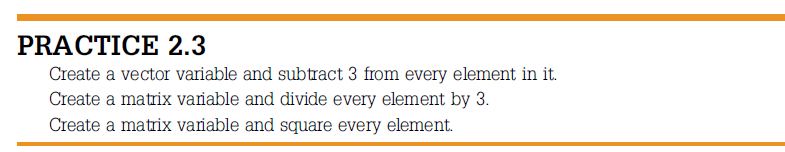

%Answer here:
vec = [2 4 6 7 8]

vec = 1×5
     2     4     6     7     8


vec - 3

ans = 1×5
    -1     1     3     4     5


vec - 3*ones(1,5)

ans = 1×5
    -1     1     3     4     5


A = [12 21 15; 300 123 66]

A = 2×3
    12    21    15
   300   123    66


A * (1/3)

ans = 2×3
     4     7     5
   100    41    22


A.^2

ans = 2×3
         144         441         225
       90000       15129        4356


A.*A

ans = 2×3
         144         441         225
       90000       15129        4356


format bank
A.*log(A)

ans = 2×3
1.0e+00 *

         29.82         63.93         40.62
       1711.13        591.90        276.52


A.*sqrt(A)

ans = 2×3
1.0e+00 *

         41.57         96.23         58.09
       5196.15       1364.14        536.19


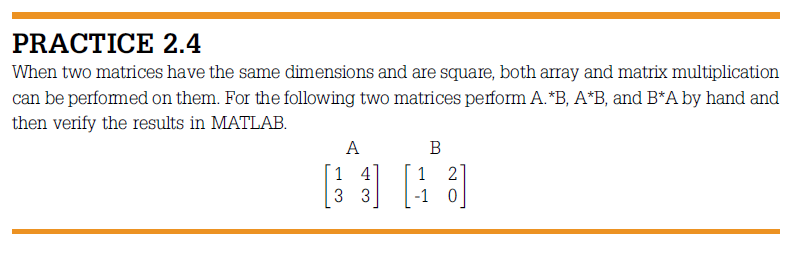

%Answer here:
A = [1 4; 3 3]; B = [1 2 ; -1 0]

B = 2×2
          1.00          2.00
         -1.00             0


A.*B 

ans = 2×2
          1.00          8.00
         -3.00             0


A*B

ans = 2×2
         -3.00          2.00
             0          6.00


B*A

ans = 2×2
          7.00         10.00
         -1.00         -4.00


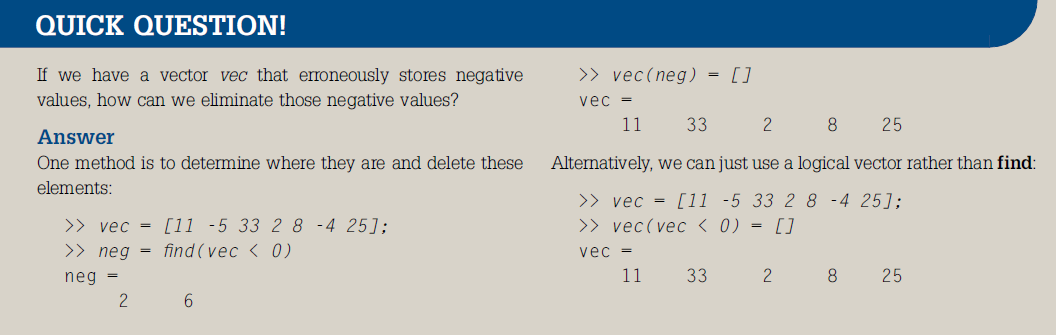

vec = [11 -5 33 2 8 -4 25]

vec = 1×7
         11.00         -5.00         33.00          2.00          8.00         -4.00         25.00


%Way number 1:
neg = find(vec<0)

neg = 1×2
          2.00          6.00


vec(neg) = [] 

vec = 1×5
         11.00         33.00          2.00          8.00         25.00


%Way number 2:
vec = [11 -5 33 2 8 -4 25]

vec = 1×7
         11.00         -5.00         33.00          2.00          8.00         -4.00         25.00


vec(vec<0) = []

vec = 1×5
         11.00         33.00          2.00          8.00         25.00


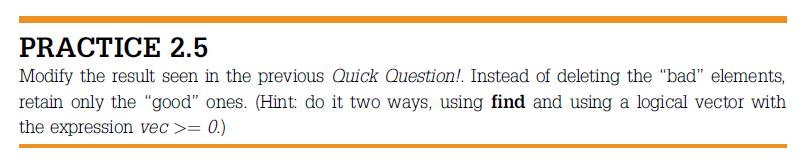

%Answer here:
vec = [11 -5 33 2 8 -4 25]

vec = 1×7
         11.00         -5.00         33.00          2.00          8.00         -4.00         25.00



vec = vec(find(vec>=0))

vec = 1×5
         11.00         33.00          2.00          8.00         25.00


vec = [11 -5 33 2 8 -4 25]

vec = 1×7
         11.00         -5.00         33.00          2.00          8.00         -4.00         25.00


vec = vec(vec>=0)

vec = 1×5
         11.00         33.00          2.00          8.00         25.00



mat = [a ; b]

Error using vertcat
Dimensions of arrays being concatenated are not consistent.

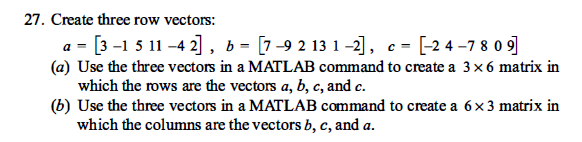



a = [3 -1 5 11 -4 2]
b = [7 -9 2 13 1 -2]
c= [-2 4 -7 8 0 9]
mat = [1 2 3; 4 5 6]
mat_a = [a ; b ; c]
%wrong: 
%mat_a = [a b c] %results in a concatenation of the three vectors
mat_b = [transpose(b) transpose(c) transpose(a)]

mat = [[1; 2; 3] [4; 5; 6] ]


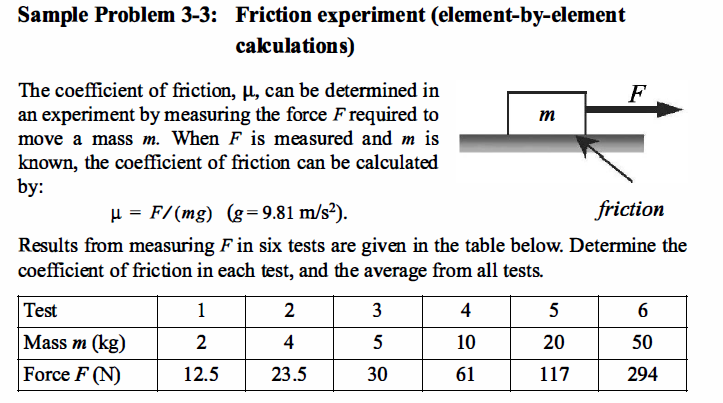

F = [12.5, 23.5, 30, 61, 117, 294]
M = [2 4 5 10 20 50]
g = 9.81
format short
friction = F./(M*g)
avg_friction = sum(friction)/length(friction)

